Mini Project 3 - Hojjat Hosseini

clear;clc;close all
dataset1 = [0 1 0 -19.00; 
1 1.95 9.37 -17.95; 
2 2.88 18.23 -16.90;
3 3.79 26.57 -15.85;
4 4.65 34.44 -14.80; 
5 5.45 41.78 -13.75; 
6 6.18 48.60 -12.70; 
7 7.48 54.91 -11.65; 
8 7.99 60.71 -10.60;
9 8.72 65.99 -9.55; 
10 9.01 70.75 -8.50; 
11 9.28 74.98 -7.45; 
12 9.46 78.70 -6.40; 
13 9.59 81.90 -5.34; 
14 9.72 84.57 -4.30; 
15 9.81 86.72 -3.25; 
16 9.88 88.34 -2.20; 
17 9.91 89.44 0;
18 9.46 78.51 -6.35;
19 9.66 81.68 -5.30;
20 9.80 84.33 -4.25;
21 9.90 86.45 -3.20;
22 9.96 88.05 -2.15;
23 10.01 89.67 0.];
dataset2 = [0 1 90 11.5;
1 1.10 79.08 9.40;
2 1.29 74.40 8.35;
3 1.56 70.24 7.30;
4 1.90 66.60 6.25;
5 2.2 63.48 5.20;
6 2.73 60.88 4.15;
7 3.22 58.81 3.10;
8 3.74 57.26 2.05;
9 4.84 55.74 -0.05;
10 5.96 56.31 -2.15;
11 6.51 57.38 -3.20;
12 7.05 58.98 -4.25;
13 7.56 61.10 -5.30;
14 8.04 63.75 -6.35;
15 8.48 66.92 -7.40;
16 8.87 70.61 -8.45;
17 9.20 74.82 -7.40];
dataset1 = dataset1(:,2:end);
dataset2 = dataset2(:,2:end);

xtr1 = dataset1(:,1:2);
ytr1 = dataset1(:,3);
xtr2 = dataset2(:,1:2);
ytr2 = dataset2(:,3);

xtr = [xtr1;xtr2];
ytr = [ytr1;ytr2];

% The aim is to reach point 10 and an angle of 90 degrees
% x1: [1,10.01]  => length=9.01   =>    x : position 
% x2: [0,90]     => length=90     =>    phi : angle of truck
% y: [-19,11.5]  => length=30.5   =>    tta : angle of wheel

% U = [0 20; -90 270; -40 40];
% U = [0 11; -1 100; -20 12];
U = [-1 12; -2 110; -30 15];
N1 = 5;
N2 = 7;
Ny = 7;
N = [N1 N2 Ny];
dim = size(U,1);

 

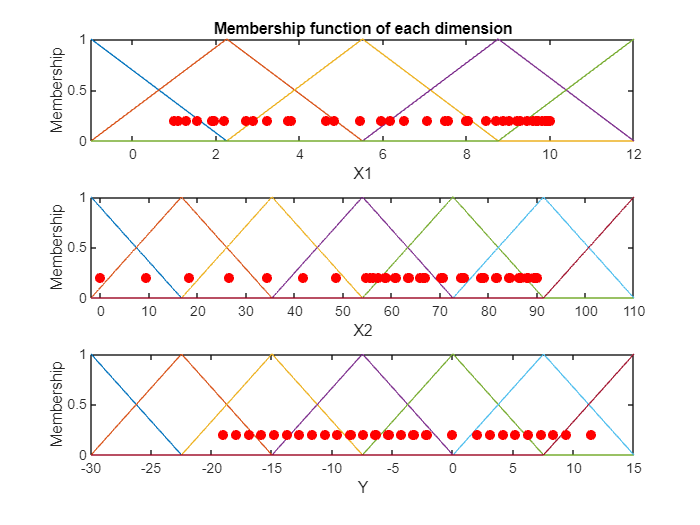

% find centers
centers = get_mf_centers(U,N,'equal');
% make params
par = get_mf_par(U,centers,'tri',true);
% add mf on x=10 and phi=90
% par{1} = [par{1};[9.5 10 10.5]];
% par{2} = [par{2};[85 90 95]];
% make mfs
MFs = get_mf_bigmtx('tri',par);
% PLOT mfs
get_mf_plot2D(U,MFs,[xtr ytr])

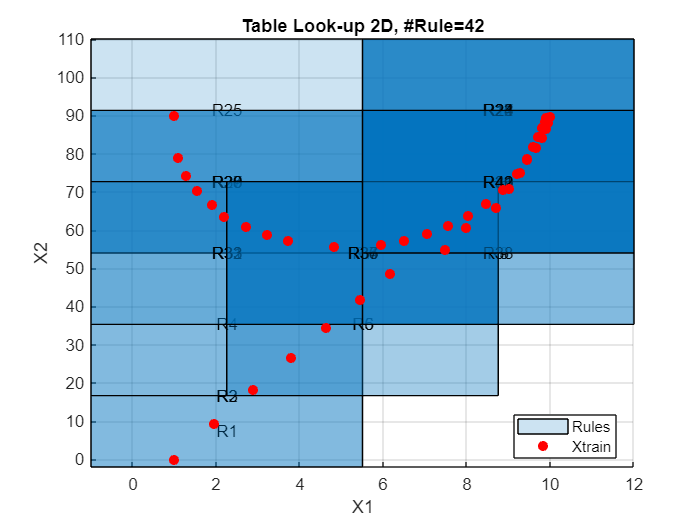

% make rules
[rule,star_value] = get_rule(MFs,[xtr ytr]);
tableLookUp2D(U,par,rule,'tri',xtr)

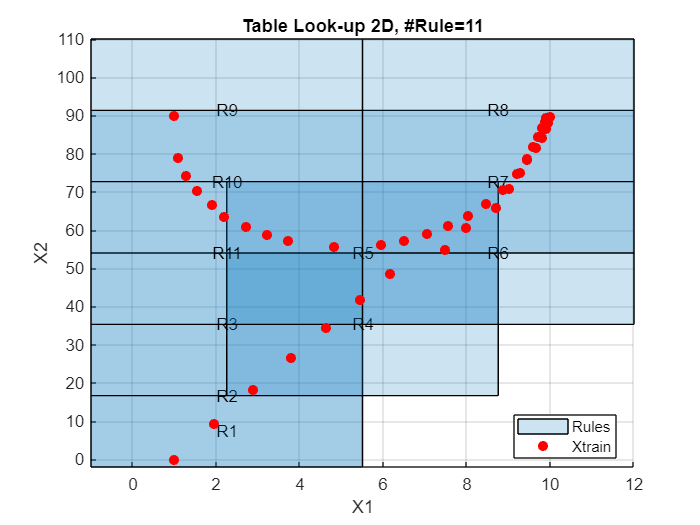

% reduce rules
rule = ruleReduction(rule,star_value);
tableLookUp2D(U,par,rule,'tri',xtr)

% make mfRule big matrix
mfRule = get_mfRule_bigmtx(rule,MFs);
xte = xtr;
yte = ytr;
ybars = centers{end};
yest = FS.COAdefuzz(xte, mfRule, ybars(rule(:,end)));
mse = sum((yest'-yte).^2)/numel(yte)

mse = 4.8590

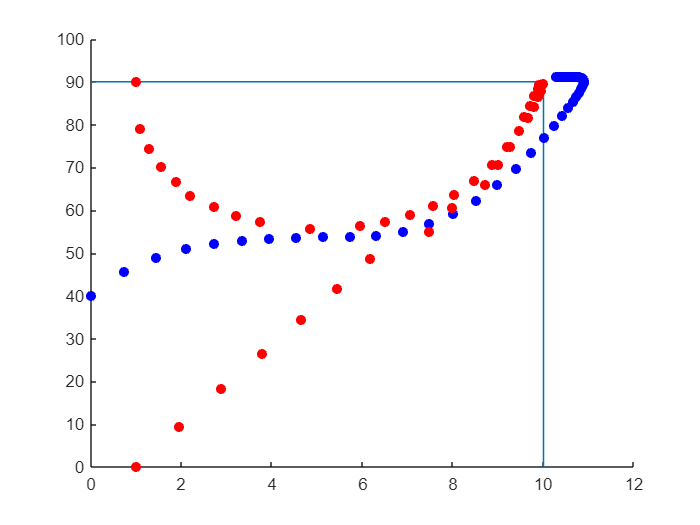

i=1;
x(i) = xtr(25,1);
phi(i) = xtr(25,2);
% x(i) = xtr(1,1);
% phi(i) = xtr(1,2);
x(i) = 0;
phi(i) = 40;
figure
scatter(x(1),phi(1),'b','filled')
hold on
line([10 10],[0 90])
line([0 10],[90 90])
while true
    tta(i) = FS.COAdefuzz([x(i) phi(i)], mfRule, ybars(rule(:,end)));
    if isnan(tta(i)), error("there is no rule for x="+x(i)+" and phi="+phi(i) ), end
    [x(i+1), ~, phi(i+1)] = truckSystemApproximation(x(i), [], phi(i), tta(i));
    scatter(x(i+1),phi(i+1),'blue','filled')
    pause(0.1)
    if abs(x(i+1)-10)<0.3 && abs(phi(i+1)-90)<2, break, end
    i=i+1;
end
% scatter(x,phi,'blue','filled')
% hold on
% line([10 10],[0 90])
% line([0 10],[90 90])
scatter(xtr(:,1),xtr(:,2),'red','filled')
hold off


rule

function [x_next, y_next, phi_next] = truckSystemApproximation(x, y, phi, theta)
    % System parameters
    b = 4; % Length of the truck
    
    % System equations
    x_next = x + cosd(phi + theta) + sind(theta) * sind(phi);
    y_next = y + sind(phi + theta) - sind(theta) * cosd(phi);
    phi_next = phi - asind(2 * sind(theta) / b);
end